## FA2 strain

modelName = 'FA2and3';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Manual Switch3",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','0') % FA2 model

p = sdo.getParameterFromModel(modelName,'IPTG');

p.Value = 100;
p.Minimum = 0;
p.Maximum = 1000;
p.Scale = 1000;
p.Free = 1;

options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

FFASignal = Simulink.SimulationData.Signal;
FFASignal.Name = 'Fatty acid';
FFASignal.BlockPath = modelName + "/GainFA";
FFASignal.PortType = 'outport';
FFASignal.PortIndex = 1;
FFASignal.Values = timeseries((1:25)',(1:25)'); % What does this mean?

Exp.OutputData = FFASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -1.4374

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 05-Nov-2023 22:09:25

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      3     -1.43736            0
    1      7     -1.60378            0         0.07         2.25
    2     15     -1.60388            0      0.00232         1.25
    3     18     -1.60403            0     0.000391       0.0148
局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされているため、
fmincon は停止しました。
 
optInput =
 
       Name: 'IPTG'
      Value: 31.9272
    Minimum: 0
    Maximum: 1000
       Free: 1
      Scale: 1000
       Info: [1×1 struct]

 
1x1 param.Continuous
 
lists of methods, superclasses
 


optInputInfo = フィールドをもつ struct :
               F: -1.6040
       Gradients: [1×1 struct]
        exitflag: 2
      iterations: 3
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 8.637677 秒です。


maxFFA_FA2 = -optInputInfo.SolverOutput.fval;

SetPointValues = logspace(0,3,100); % 1-1000 uM IPTG
spv_length = length(SetPointValues);
for i = 1:1:spv_length
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setBlockParameter(modelName + "/To optimize input",...
        'Value',num2str(SetPointValues(i)));
end

out_FA2 = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[05-Nov-2023 21:37:12] シミュレーションの実行中...
[05-Nov-2023 21:37:13] シミュレーション実行 1/100 が完了
[05-Nov-2023 21:37:14] シミュレーション実行 2/100 が完了
[05-Nov-2023 21:37:14] シミュレーション実行 3/100 が完了
[05-Nov-2023 21:37:14] シミュレーション実行 4/100 が完了
[05-Nov-2023 21:37:15] シミュレーション実行 5/100 が完了
[05-Nov-2023 21:37:15] シミュレーション実行 6/100 が完了
[05-Nov-2023 21:37:16] シミュレーション実行 7/100 が完了
[05-Nov-2023 21:37:16] シミュレーション実行 8/100 が完了
[05-Nov-2023 21:37:17] シミュレーション実行 9/100 が完了
[05-Nov-2023 21:37:17] シミュレーション実行 10/100 が完了
[05-Nov-2023 21:37:18] シミュレーション実行 11/100 が完了
[05-Nov-2023 21:37:18] シミュレーション実行 12/100 が完了
[05-Nov-2023 21:37:18] シミュレーション実行 13/100 が完了
[05-Nov-2023 21:37:19] シミュレーション実行 14/100 が完了
[05-Nov-2023 21:37:19] シミュレーション実行 15/100 が完了
[05-Nov-2023 21:37:21] シミュレーション実行 16/100 が完了
[05-Nov-2023 21:37:21] シミュレーション実行 17/100 が完了
[05-Nov-2023 21:37:22] シミュレーション実行 18/100 が完了
[05-Nov-2023 21:37:22] シミュレーション実行 19/100 が完了
[05-Nov-2023 21:37:23] シミュレーション実行 20/100 が完了
[05-Nov-2023 21:37:23] シミュレーション実行 21/100 が完了
[05-Nov-2023 21:37:24] シミ

out_FA2 = 1x100 Simulink.SimulationOutput 配列



FFAfinal = zeros(spv_length,2);
FFAfinal(:,1) = SetPointValues;
for i = 1:1:spv_length
    FFAfinal(i,2) = out_FA2(i).logsout{1}.Values.Data(end);
end

FFAData = zeros(6,2);
FFAData(:,1) = [0 10 40 100 400 1000]';
load("FA2Data.mat")
for expIdx = 1:6
    FFAData(expIdx,2) = FA2Data(8,expIdx + 1,2);
end

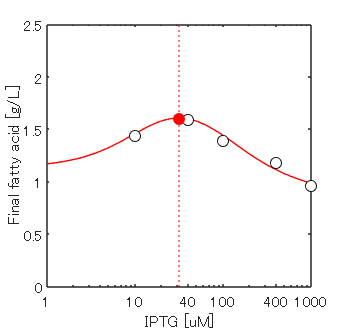

figure('Position', [120 120 250 240]);
plot(FFAfinal(:,1),FFAfinal(:,2),'r-')
xline(optInput.Value,'r:')
xlim([1 1000])
ylim([0 2.5])
xlabel('IPTG [uM]')
xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
hold on
plot(FFAData(:,1),FFAData(:,2),'ko','MarkerFaceColor','w')
plot(optInput.Value,maxFFA_FA2,'ro','MarkerFaceColor','r')
hold off
set(gca,'xscale','log')

sdo.setValueInModel(modelName,optInput);